# Compte rendu du travail n°2:

## Contexe:

On définie une fonction continue par morceau et $2pi$ périodique. 

## Preambule et initialisation du repertoire de travail:

clc ; clear;close all;
format long
global T
T = 2*pi;
f = @(t) 1.*((mod(abs(t),T)<=1/4) + (mod(abs(t),T)>2*pi -1/4))

f = function_handle with value:
    @(t)1.*((mod(abs(t),T)<=1/4)+(mod(abs(t),T)>2*pi-1/4))


Question A:

x=linspace(-4*pi,4*pi,100)

x =  -12.566370614359172 -12.312504541341815 -12.058638468324459 -11.804772395307101 -11.550906322289745 -11.297040249272387 -11.043174176255031 -10.789308103237673 -10.535442030220317 -10.281575957202959 -10.027709884185603  -9.773843811168245  -9.519977738150889  -9.266111665133531  -9.012245592116175  -8.758379519098817  -8.504513446081461  -8.250647373064103  -7.996781300046746  -7.742915227029389  -7.489049154012032  -7.235183080994675  -6.981317007977319  -6.727450934959961  -6.473584861942604  -6.219718788925246  -5.965852715907889  -5.711986642890533  -5.458120569873176  -5.204254496855818  -4.950388423838462  -4.696522350821105  -4.442656277803747  -4.188790204786391  -3.934924131769034  -3.681058058751677  -3.427191985734320  -3.173325912716962  -2.919459839699606  -2.665593766682250  -2.411727693664892  -2.157861620647536  -1.903995547630178  -1.650129474612822  -1.396263401595466  -1.142397328578106  -0.888531255560750  -0.634665182543392  -0.380799109526036  -0.12693303650

plot(x,f(x),'LineWidth',2)
hold on;
N = [4 8 16 32 64 100];
col = ['r','g','y','b','m','r','g','y','b','m']

col = 'rgybmrgybm'

t = x

t =  -12.566370614359172 -12.312504541341815 -12.058638468324459 -11.804772395307101 -11.550906322289745 -11.297040249272387 -11.043174176255031 -10.789308103237673 -10.535442030220317 -10.281575957202959 -10.027709884185603  -9.773843811168245  -9.519977738150889  -9.266111665133531  -9.012245592116175  -8.758379519098817  -8.504513446081461  -8.250647373064103  -7.996781300046746  -7.742915227029389  -7.489049154012032  -7.235183080994675  -6.981317007977319  -6.727450934959961  -6.473584861942604  -6.219718788925246  -5.965852715907889  -5.711986642890533  -5.458120569873176  -5.204254496855818  -4.950388423838462  -4.696522350821105  -4.442656277803747  -4.188790204786391  -3.934924131769034  -3.681058058751677  -3.427191985734320  -3.173325912716962  -2.919459839699606  -2.665593766682250  -2.411727693664892  -2.157861620647536  -1.903995547630178  -1.650129474612822  -1.396263401595466  -1.142397328578106  -0.888531255560750  -0.634665182543392  -0.380799109526036  -0.12693303650

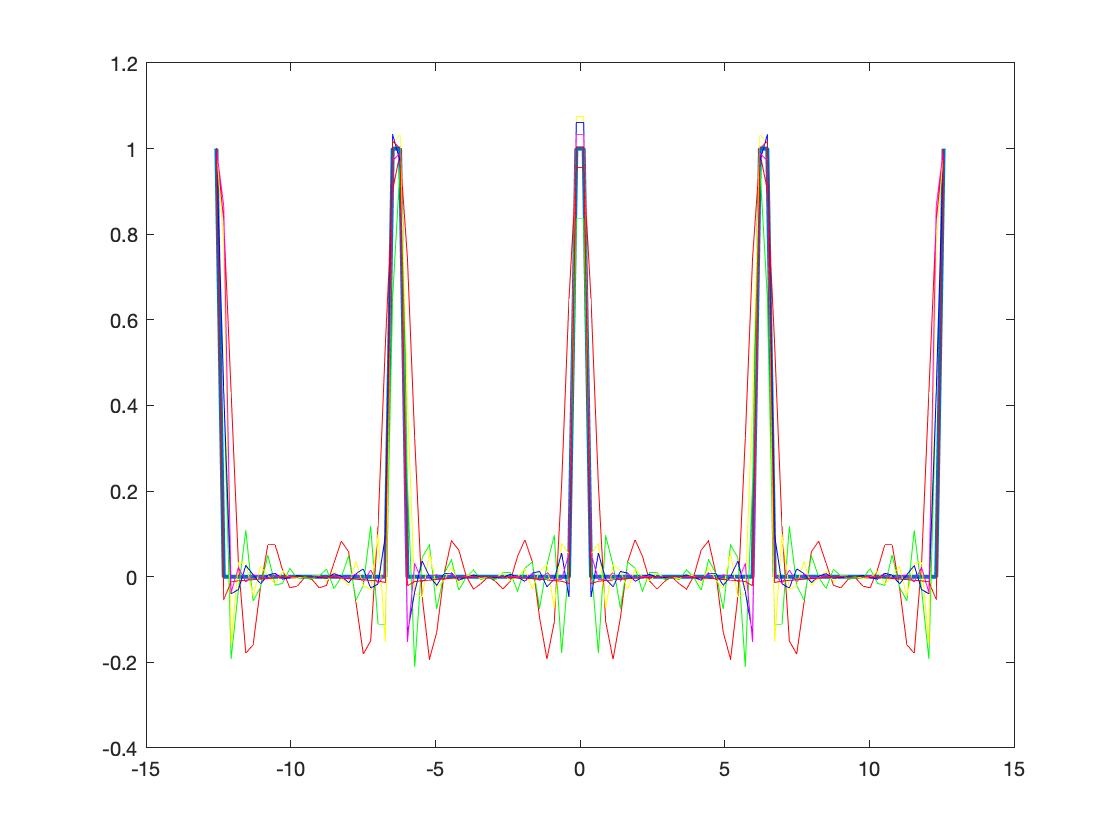

Sn =      0


Sn =      0


Sn =      0


Sn =      0


Sn =      0


Sn =      0


for k=1:length(N)
   [C,F] = FD2(N(k),f);
   Sn = 0
   for j = (-N(k)+1):N(k)
       Sn = Sn + fourrier_discret(N(k),j,f).*exp(i*j*t);
   end
   line(x,Sn,'Color',col(k));
   norm(C)^2;
   [C2,F2] = FD(N(k),f);
end

## On observe ici le phénomène Gibbs, on va donc utiliser les sommes de fejer.

## Question C:

figure;
FD(8,f)

ans =    0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000


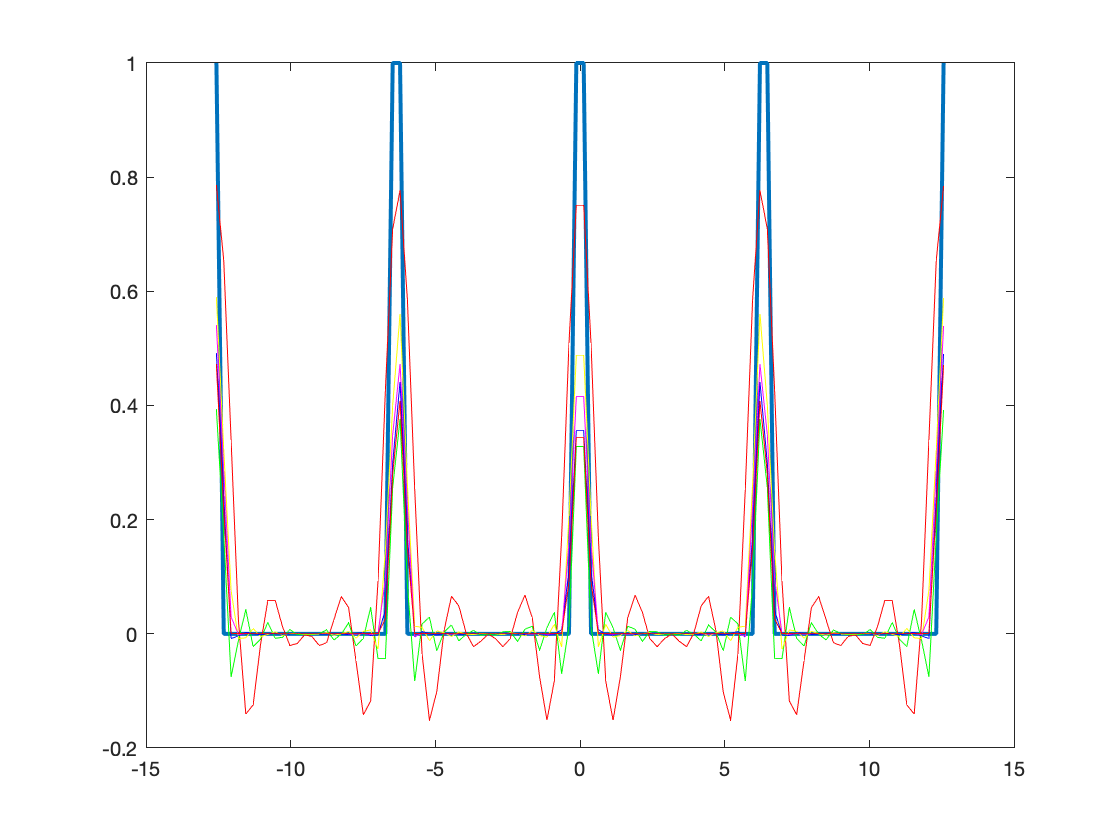

plot(x,f(x),'LineWidth',2)
hold on;
for k=1:length(N)
   [C,F] = FD2(N(k),f);
   Sn = 0;
   for j = (-N(k)+1):N(k)
       Sn = Sn + (fourrier_discret(N(k),j,f)^2).*exp(i*j*t);
   end
   Sn = 2*pi*Sn;
   line(x,Sn,'Color',col(k));
   norm(C)^2;
   [C2,F2] = FD(N(k),f);
end

## Annexes

function [S] = intervalle(N)
S = zeros(1,2*N);
for i=1:2*N
    S(i) = ((i-1)*pi)/N;
end
end

function [fd] = fourrier_discret(N,k,f)
fd = 0;
for j=1:2*N
    fd = fd + f(((j-1)*pi)/N)*exp((-1i*pi*k*(j-1))/N);
end
fd = fd/(2*N);
end


function [Fd,Fn] = FD(N,f)
    Fd = zeros((2*N),0);
    Fn = zeros((2*N),0);
    for j=1:(2*N)
        Fn(j) = f((pi/N)*(j-1))*exp(((-1i)*(N+1)*pi*(j-1)/N));
        Fd(j) = fourrier_discret(N,j-N,f);
    end
end

function [Fd,Fn] = FD2(N,f)
    om = omega(2*N);
    Fn = f(intervalle(N)) .*(exp((-1i*pi)/N).^((N+1).*(0:((2*N)-1))));
    Fd = (1/(2*N)).*om*Fn';
end


function [Ome] = omega(m)
Ome = zeros(m,m);
for j=1:m
    for l=1:m
        Ome(j,l) = exp((-2*1i*pi*(j-1)*(l-1))/m);
    end
end
end
